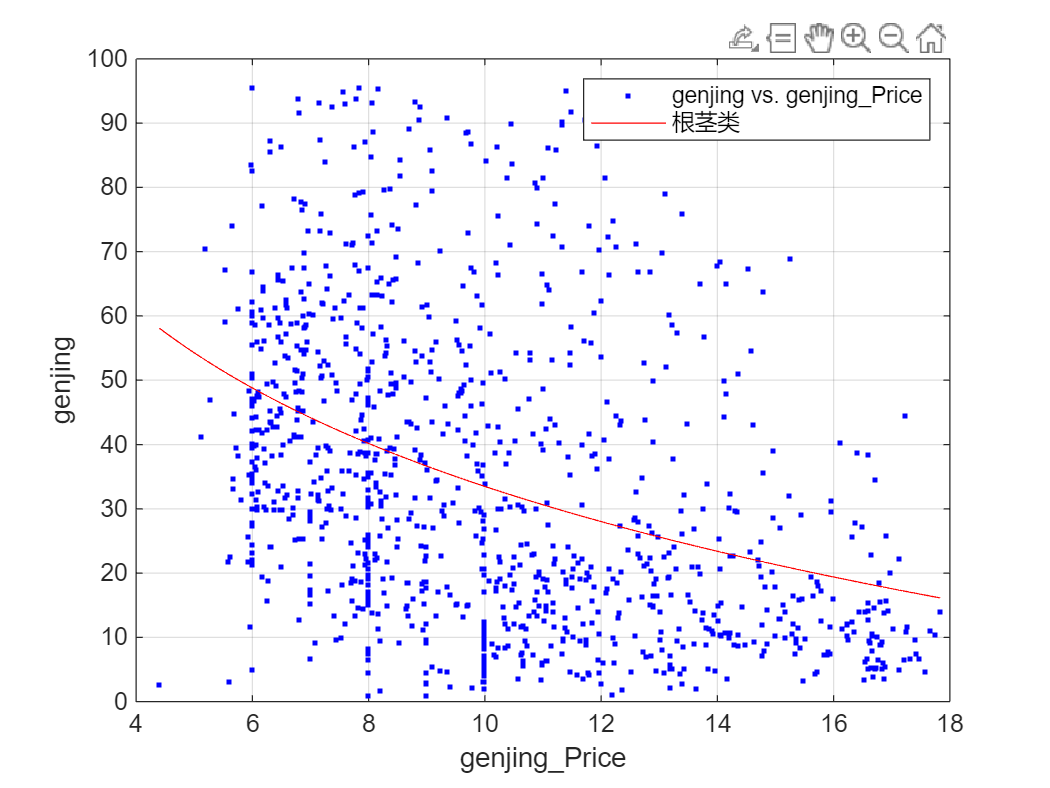

clear,clc
load wash_Types.mat
load wash_Types_Price.mat

huacai=wash_Types(:,1);
huaye=wash_Types(:,2);
lajiao=wash_Types(:,3);
qie=wash_Types(:,4);
shiyongjun=wash_Types(:,5);
genjing=wash_Types(:,6);

huacai_Price=wash_Type_Price(:,1);
huaye_Price=wash_Type_Price(:,2);
lajiao_Price=wash_Type_Price(:,3);
qie_Price=wash_Type_Price(:,4);
shiyongjun_Price=wash_Type_Price(:,5);
genjing_Price=wash_Type_Price(:,6);

%% 拟合: '根茎类'。
[xData, yData] = prepareCurveData( genjing_Price, genjing );

% 设置 fittype 和选项。
ft = fittype( 'log' );

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft );

% 绘制数据拟合图。
figure( 'Name', '根茎类' );
h = plot( fitresult, xData, yData );
legend( h, 'genjing vs. genjing_Price', '根茎类', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( 'genjing_Price', 'Interpreter', 'none' );
ylabel( 'genjing', 'Interpreter', 'none' );
grid on

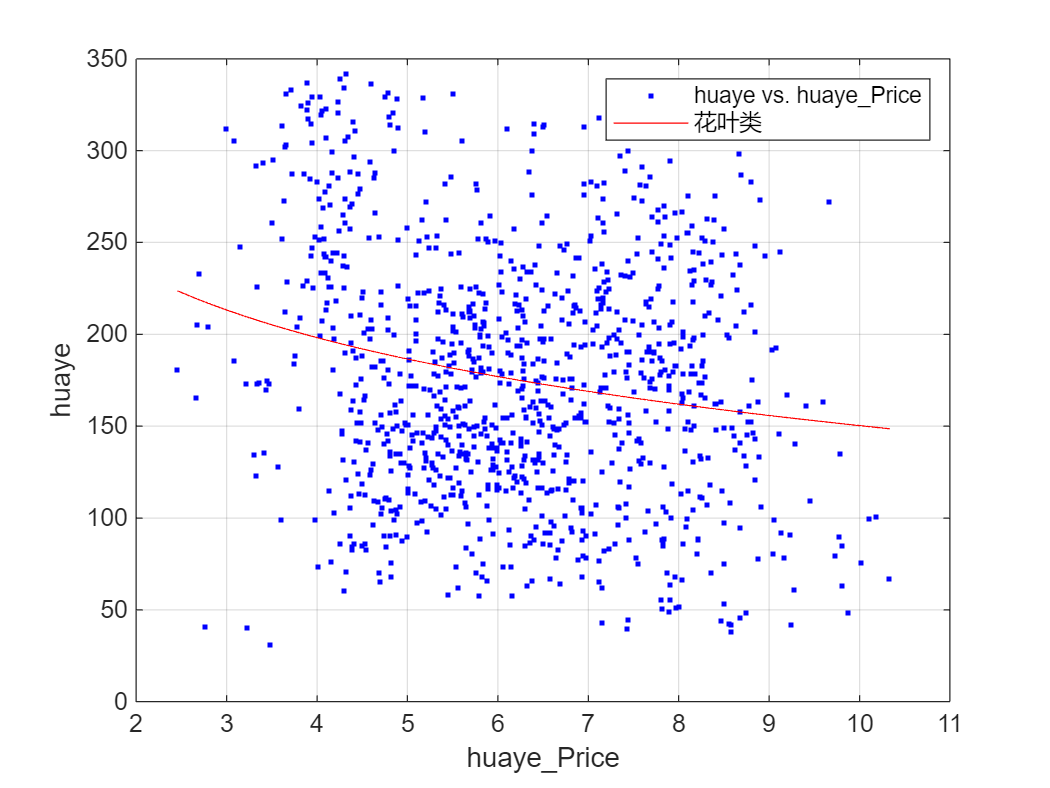


%% 拟合: '花叶类'。
[xData, yData] = prepareCurveData( huaye_Price, huaye );

% 设置 fittype 和选项。
ft = fittype( 'log' );

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft );

% 绘制数据拟合图。
figure( 'Name', '花叶类' );
h = plot( fitresult, xData, yData );
legend( h, 'huaye vs. huaye_Price', '花叶类', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( 'huaye_Price', 'Interpreter', 'none' );
ylabel( 'huaye', 'Interpreter', 'none' );
grid on

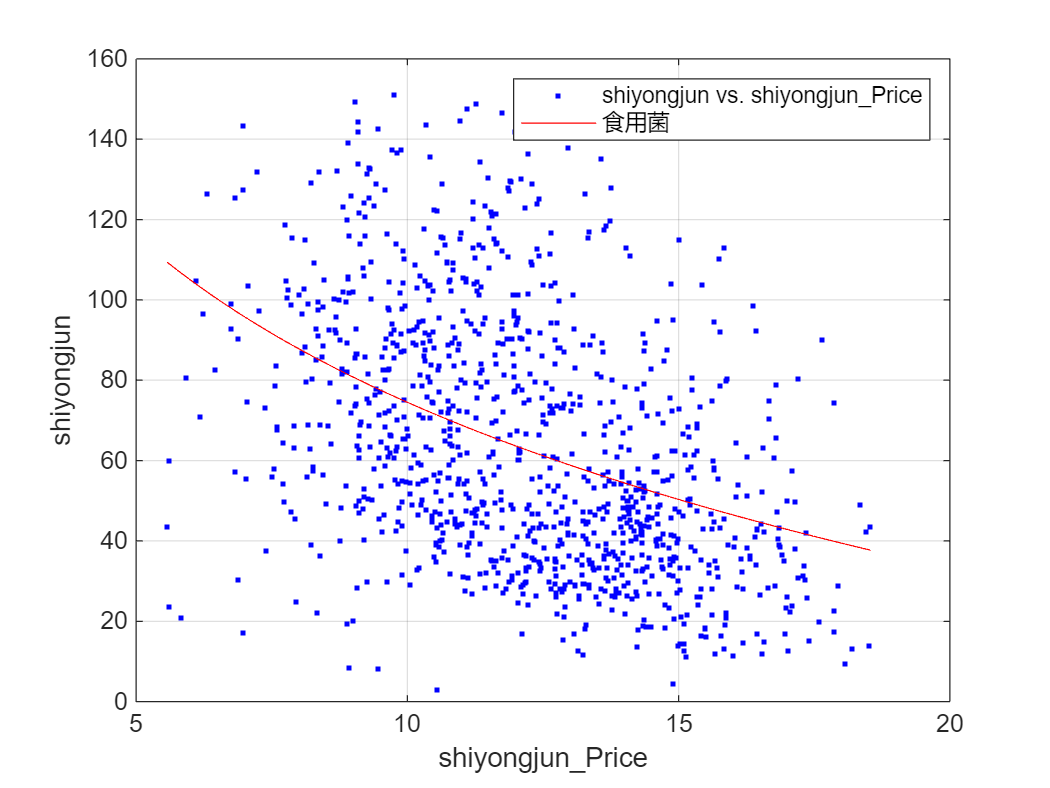


%% 拟合: '食用菌'。
[xData, yData] = prepareCurveData( shiyongjun_Price, shiyongjun );

% 设置 fittype 和选项。
ft = fittype( 'log' );

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft );

% 绘制数据拟合图。
figure( 'Name', '食用菌' );
h = plot( fitresult, xData, yData );
legend( h, 'shiyongjun vs. shiyongjun_Price', '食用菌', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( 'shiyongjun_Price', 'Interpreter', 'none' );
ylabel( 'shiyongjun', 'Interpreter', 'none' );
grid on

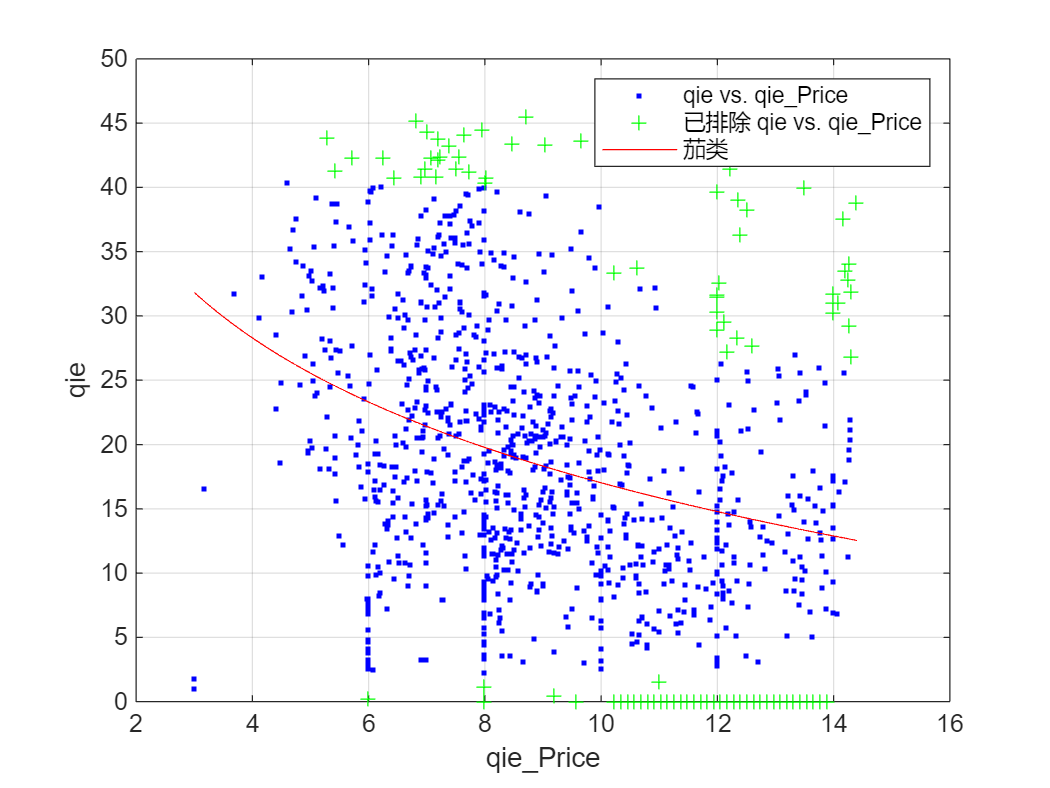


%% 拟合: '茄类'。
[xData, yData] = prepareCurveData( qie_Price, qie );

% 设置 fittype 和选项。
ft = fittype( 'log' );
excludedPoints = excludedata( xData, yData, 'Indices', [12 13 23 28 29 33 34 46 68 82 95 96 98 197 219 221 222 223 224 225 226 228 229 230 234 317 325 424 445 529 572 573 579 580 581 582 583 585 645 669 670 679 680 681 687 702 716 730 799 801 802 803 804 805 806 807 808 809 810 811 812 813 814 815 816 817 818 819 820 821 822 823 824 825 826 827 828 829 830 831 832 833 868 878 879 919 923 924 927 928 929 930 931 932 981 1024 1066] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图。
figure( 'Name', '茄类' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'qie vs. qie_Price', '已排除 qie vs. qie_Price', '茄类', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( 'qie_Price', 'Interpreter', 'none' );
ylabel( 'qie', 'Interpreter', 'none' );
grid on

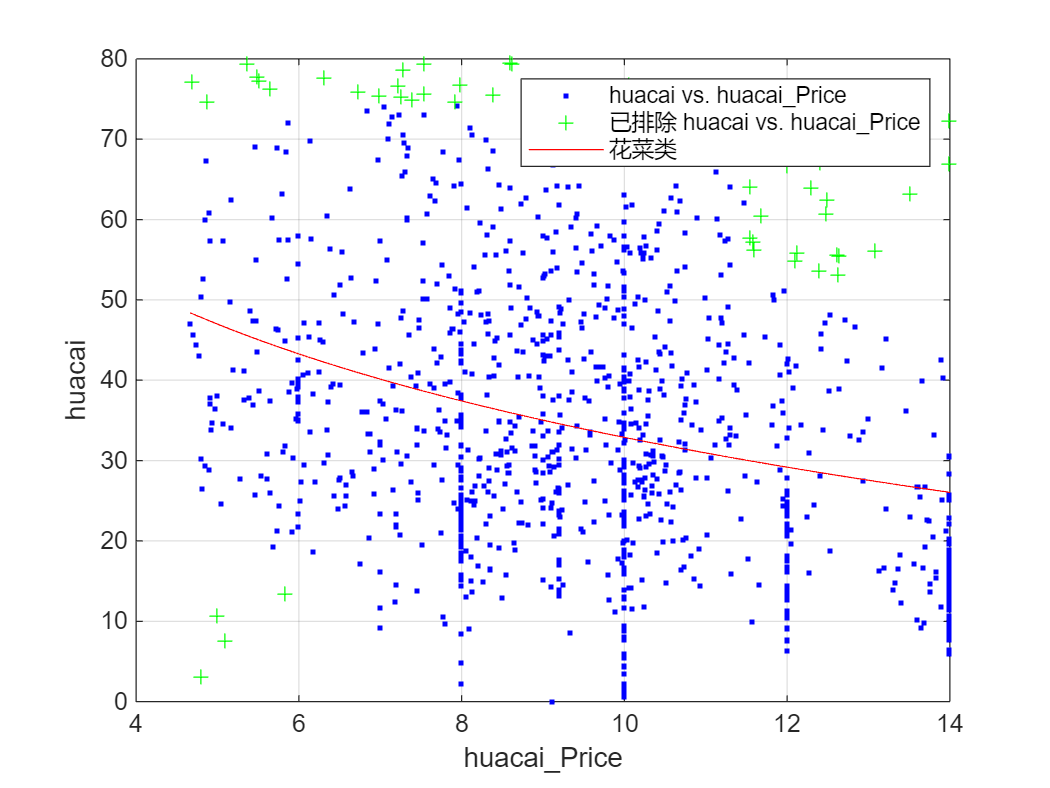


%% 拟合: '花菜类'。
[xData, yData] = prepareCurveData( huacai_Price, huacai );

% 设置 fittype 和选项。
ft = fittype( 'log' );
excludedPoints = excludedata( xData, yData, 'Indices', [4 5 11 19 26 40 42 46 72 92 93 94 101 103 135 138 142 146 151 152 166 208 221 240 277 289 374 380 752 765 766 767 770 788 792 793 794 798 799 800 801 807 813 820 849 854 875 876 877 895] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图。
figure( 'Name', '花菜类' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'huacai vs. huacai_Price', '已排除 huacai vs. huacai_Price', '花菜类', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( 'huacai_Price', 'Interpreter', 'none' );
ylabel( 'huacai', 'Interpreter', 'none' );
grid on

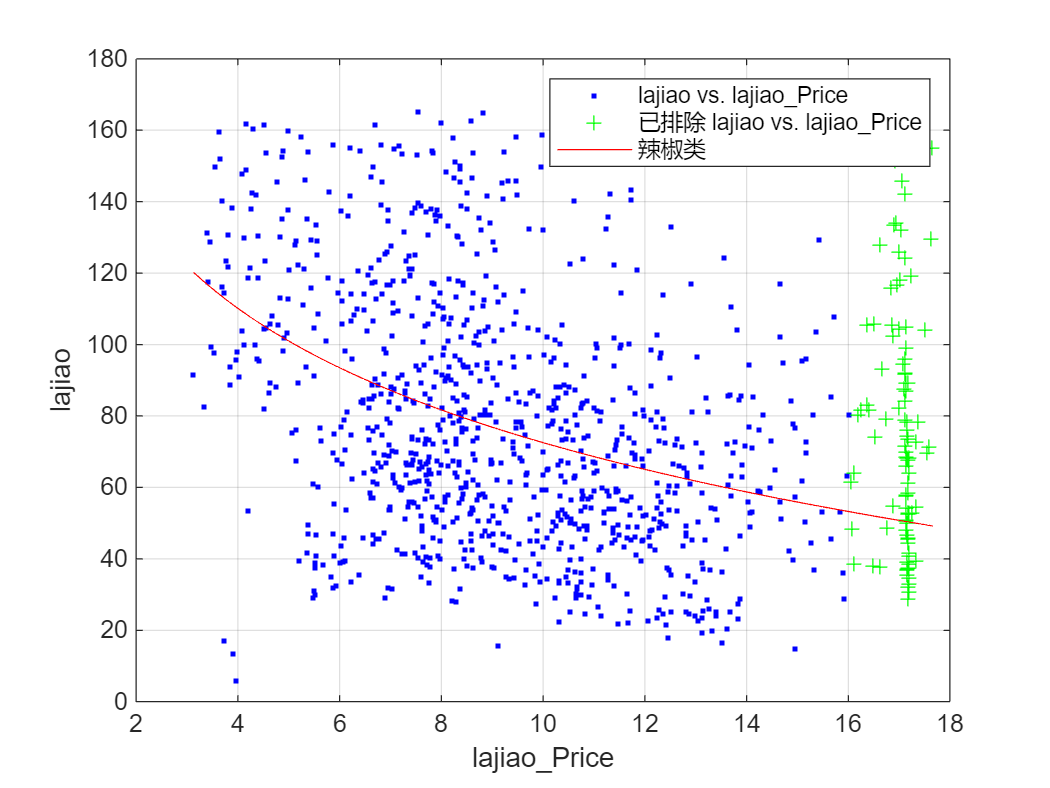


%% 拟合: '辣椒类'。
[xData, yData] = prepareCurveData( lajiao_Price, lajiao );

% 设置 fittype 和选项。
ft = fittype( 'log' );
excludedPoints = excludedata( xData, yData, 'Indices', [159 160 161 165 167 168 169 170 171 172 173 174 175 176 177 178 179 180 181 182 183 184 185 186 187 188 189 190 191 192 193 194 195 196 197 198 199 200 201 202 203 204 205 206 207 208 209 210 211 212 213 214 215 216 217 218 219 220 221 222 223 224 225 226 227 228 229 230 231 232 233 234 573 574 575 576 577 578 579 580 581 582 583 584 585 586 611 625 626 627 628 629 630 631 632 633 635 636 638 641 642] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图。
figure( 'Name', '辣椒类' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'lajiao vs. lajiao_Price', '已排除 lajiao vs. lajiao_Price', '辣椒类', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( 'lajiao_Price', 'Interpreter', 'none' );
ylabel( 'lajiao', 'Interpreter', 'none' );
grid on